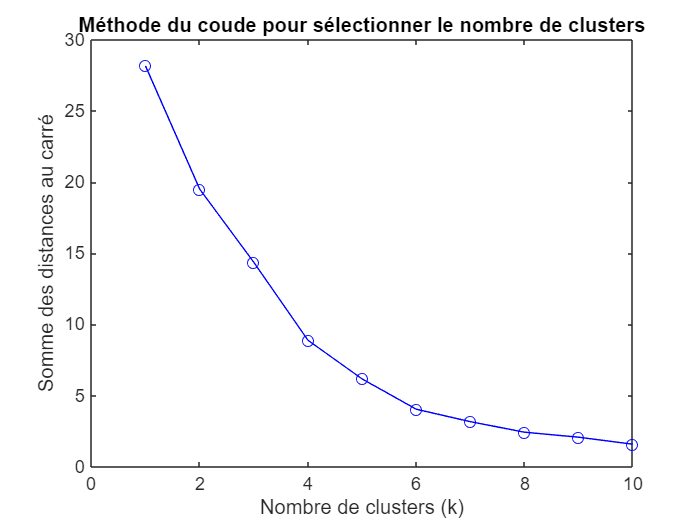

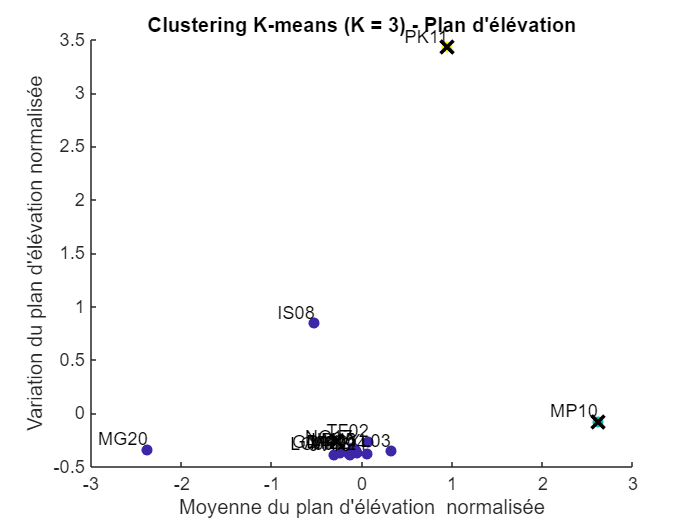

Score de silhouette moyen : 0.863
Cluster 1: MF01, TF02, YL03, IS08, LC09, JM13, GD14, LD15, NQ17, JV18, MG20, AP22, TM24
Cluster 2: MP10
Cluster 3: PK11


%% ================= Traitement cinématique ================= %%       
clear; clc; close all;

%% -------- Chargement de l'environnement -------- %%
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\3D Kinematics and Inverse Dynamics'));

%% -------- Configuration des sujets -------- %%
% AllSubjects = {'MF01', 'TF02', 'YL03', 'SC04', 'RF05', 'AP06', ...
%                'TD07', 'IS08', 'LC09', 'MP10', 'PK11', ...
%                'TF12', 'JM13', 'GD14', 'LD15', 'LM16', 'NQ17', 'JV18', ...
%                'EG19', 'MG20', 'LB21', 'AP22', 'SC23', ...
%                'TM24', 'EG25', 'RL26'};

AllSubjects = {'MF01', 'TF02', 'YL03', ...
               'IS08', 'LC09', 'MP10', 'PK11', ...
               'JM13', 'GD14', 'LD15', 'NQ17', 'JV18', ...
               'MG20', 'AP22', ...
               'TM24'};

%% -------- Fonction pour extraire les angles d'un sujet -------- %%
function [Angles_HT, time] = extract_HT_angles(subject, movement_choice)
    % Chemins et configuration
    chemin_dossier = sprintf('C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s', subject);
    
    % Noms de fichiers
    file_names = {
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL1-.c3d', subject, subject), ...
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL2-.c3d', subject, subject), ...
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL3-.c3d', subject, subject), ...
        sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL4-.c3d', subject, subject)
    };
    
    % Sélection du fichier
    fichier = fullfile(chemin_dossier, file_names{movement_choice});
    
    % Lecture du fichier C3D
    c3dH = btkReadAcquisition(fichier);
    
    % Extraction des marqueurs
    markers = btkGetMarkers(c3dH);
    nFrames = btkGetLastFrame(c3dH);
    fs = 200;
    time = (0:nFrames-1) / fs;
    
    % Initialisation des matrices pour stocker les angles
    Angles_HT = zeros(nFrames, 3);
    normalize_vector = @(v) v / norm(v);
    
    % Extraction des angles d'Euler
    for i = 1:nFrames
        % Repère du thorax
        SJN = markers.SJN(i,:); CV7 = markers.CV7(i,:);
        TV8 = markers.TV8(i,:); SXS = markers.SXS(i,:);
        Ot = SJN;
        Yt = normalize_vector(mean([SXS; TV8]) - mean([SJN; CV7]));
        Zt = normalize_vector(cross(SJN - CV7, mean([SXS; TV8]) - SJN));
        Xt = normalize_vector(cross(Yt, Zt));
        
        % Repère de l'humérus
        RGH = markers.RSCT(i,:); RHME = markers.RHME(i,:); RHLE = markers.RHLE(i,:);
        Rmid_HLE_HME = mean([RHLE; RHME]);
        Oh = RGH;
        Yh = normalize_vector(RGH - Rmid_HLE_HME);
        Xh = normalize_vector(cross(RGH - RHLE, RGH - RHME));
        Zh = normalize_vector(cross(Yh, Xh));
        
        % Matrices de rotation
        Rt = [Xt', Yt', Zt'];
        Rh = [Xh', Yh', Zh'];
        
        % Correction orthonormalité
        [Ut,~,Vt] = svd(Rt); Rt = Ut * Vt';
        [Uh,~,Vh] = svd(Rh); Rh = Uh * Vh';
        
        % Rotation Huméro-Thoracique
        R_HT = Rt' * Rh;
        
        % Extraction des angles d'Euler
        Angles_HT(i,:) = squeeze(R2mobileYXY_array3(reshape(R_HT,3,3,1)));
    end
    
    % Filtrage et correction
    Angles_HT = unwrap(Angles_HT);
    fc = 6;
    [b, a] = butter(2, fc / (fs/2), 'low');
    Angles_HT = filtfilt(b, a, Angles_HT);
    
    % Recentrage des angles
    for j = 1:3
        Angles_HT(:,j) = Angles_HT(:,j) - mean(Angles_HT(1:10,j));
    end
end

% %% -------- Clustering des plans d'élévation -------- %%
function analyze_elevation_planes(subjects)
    % Matrice pour stocker les caractéristiques des plans d'élévation
    elevation_features = [];
    subject_labels = {};
    
    % Extraire les caractéristiques pour chaque sujet
    for i = 1:length(subjects)
        try
            % Sélection mouvement spécifique (1-4)
            [Angles_HT, time] = extract_HT_angles(subjects{i}, 2);
            angle_plan = rad2deg(Angles_HT(:,1));
            n_top = 150; % Nombre d'échantillons max du pic à considérer
            
            % Extraire les n_top plus grandes valeurs absolues
            [~, idx_sorted] = sort(abs(angle_plan), 'descend');
            top_values = angle_plan(idx_sorted(1:n_top));
            
            % Caractéristiques enrichies
            features = [
                mean(top_values), ...       % Moyenne 
                std(top_values), ...        % Écart-type
                median(top_values), ...     % Médiane
                skewness(top_values), ...   % Asymétrie
                kurtosis(top_values), ...   % Kurtosis
                max(abs(top_values)), ...   % Amplitude maximale
                range(top_values)           % Étendue
            ];
            
            elevation_features = [elevation_features; features];
            subject_labels{end+1} = subjects{i};
        catch
            fprintf('Erreur lors du traitement du sujet %s\n', subjects{i});
        end
    end
    
    % Normalisation des caractéristiques
    features_normalized = (elevation_features - mean(elevation_features)) ./ std(elevation_features);
    
    % Méthode du coude pour sélectionner le nombre optimal de clusters
    max_k = 10;
    sum_squared_distances = zeros(1, max_k);
    
    for k = 1:max_k
        [idx, centroids] = kmeans(features_normalized, k, 'Replicates', 10);
        sum_squared_distances(k) = sum(min(pdist2(features_normalized, centroids), [], 2));
    end
    
    % Tracer la courbe du coude
    figure;
    plot(1:max_k, sum_squared_distances, 'bo-');
    title('Méthode du coude pour sélectionner le nombre de clusters');
    xlabel('Nombre de clusters (k)');
    ylabel('Somme des distances au carré');
    
    % Sélection basée sur la méthode du coude (par exemple, k = 3)
    k_optimal = 3;
    
    % Clustering K-means avec le nombre optimal de clusters
    [idx, centroids] = kmeans(features_normalized, k_optimal, 'Replicates', 10);
    
    % Visualisation des clusters
    figure;
    scatter(features_normalized(:,1), features_normalized(:,2), [], idx, 'filled');
    title(sprintf('Clustering K-means (K = %d) - Plan d''élévation', k_optimal));
    xlabel('Moyenne du plan d''élévation  normalisée');
    ylabel('Variation du plan d''élévation normalisée');
    
    % Afficher les étiquettes des sujets
    for i = 1:size(features_normalized, 1)
        text(features_normalized(i,1), features_normalized(i,2), subject_labels{i}, ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
    end
    
    % Afficher les centroïdes
    hold on;
    plot(centroids(:,1), centroids(:,2), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
    
    % Calcul de la silhouette
    silhouette_scores = silhouette(features_normalized, idx);
    mean_silhouette = mean(silhouette_scores);
    fprintf('Score de silhouette moyen : %.3f\n', mean_silhouette);
    
    % Récapitulatif des clusters
    cluster_summary = cell(k_optimal, 1);
    for c = 1:k_optimal
        cluster_subjects = subject_labels(idx == c);
        cluster_summary{c} = strjoin(cluster_subjects, ', ');
        fprintf('Cluster %d: %s\n', c, cluster_summary{c});
    end
end

%% -------- Exécution de l'analyse -------- %%
% Lancer l'analyse de clustering
analyze_elevation_planes(AllSubjects);